# A Estimation curve VS different S_EI:L6 added

## first, setup connctivity map

CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

load('NtWk_Archit.mat')

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.52;  % was 1.5
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Network Simulation

Elapsed time is 5.911730 seconds.
Elapsed time is 8.799691 seconds.
Elapsed time is 11.651455 seconds.
Elapsed time is 14.472048 seconds.
Elapsed time is 17.313564 seconds.
Elapsed time is 20.188169 seconds.
Elapsed time is 22.962334 seconds.
Elapsed time is 25.779046 seconds.


S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

Elapsed time is 28.912341 seconds.
Elapsed time is 31.788142 seconds.
Elapsed time is 34.760795 seconds.
Elapsed time is 37.757069 seconds.
Elapsed time is 40.685152 seconds.
Elapsed time is 43.662899 seconds.
Elapsed time is 46.727241 seconds.
Elapsed time is 49.742949 seconds.
Elapsed time is 53.018847 seconds.
Elapsed time is 56.302496 seconds.


S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

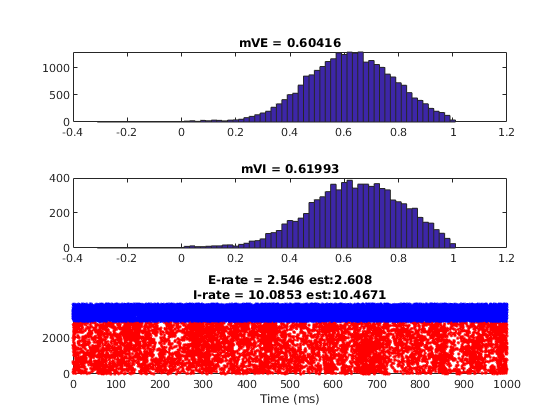

Elapsed time is 59.813827 seconds.
Elapsed time is 63.146707 seconds.
Elapsed time is 66.528022 seconds.
Elapsed time is 70.041644 seconds.
Elapsed time is 73.530840 seconds.
Elapsed time is 77.115481 seconds.
Elapsed time is 80.560718 seconds.
Elapsed time is 84.162036 seconds.
Elapsed time is 87.808809 seconds.
Elapsed time is 91.598479 seconds.


S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

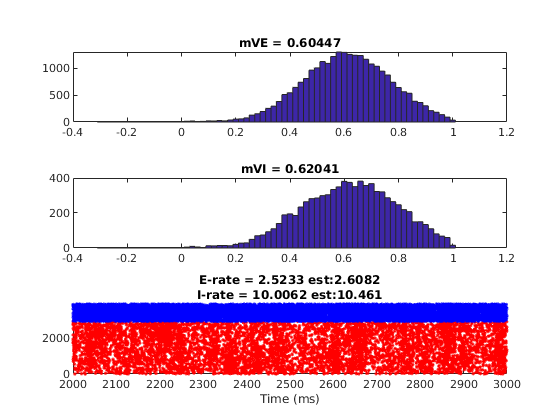

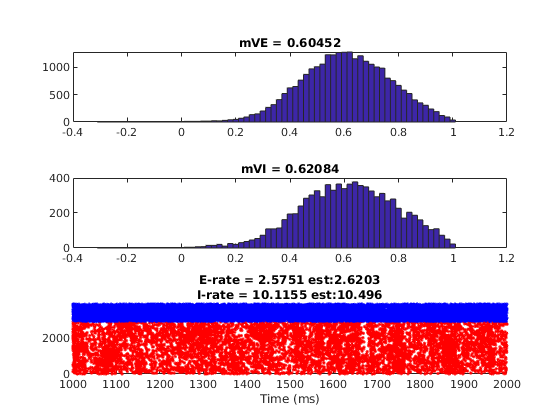

Elapsed time is 95.532327 seconds.


%% Network Simulation
T = 3000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.3; N_EEDly = floor(T_EEDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute Neuron Ind
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
InSs = load('Initials_L6.mat');
RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);

%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE,C_EI,C_IE,C_II,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        %E_Ind = 10000:13000; I_Ind = 3300:4300;
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        %close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
        toc
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end

toc

Elapsed time is 95.537953 seconds.



NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop



## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X),'single');
OD_EMap = zeros(n_E_HC*N_HC,'single');
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lgnE_Drive = [60,50,42,50]*4/1e3;
lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(OD_E)';
lambda_I_drive = lgnI_Drive;

L6E_Drive = [50 35 20 35]*50/1e3;
L6I_Drive = min(L6E_Drive);
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
T = 10000; dt = 0.1;
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

%   [A,~,Times] = find(eventsN);
%   R = sparse(A,floor(Times/dt)+1,ones(size(A)),N,length(t));

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .4; N_EEDly = floor(T_EEDly/dt);

% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation
load('DriveWkSp_10.mat','EndState');
RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
                                                             GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
                                                                GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
EEDlyRcd = sparse(N_E,N_EEDly);

% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

But to accelerate, we exclude L6 Current Input at first...

TPar = 10;
for TSec = 11:TPar+10
tic
for TimeN = 1:floor(T/dt/TPar)
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) + lambda_E_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                      + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                      + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
     
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
          V1NetworkUpdate_Ver3_Drive_PoissonRead(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                          GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                          RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                          GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                          EEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE,C_EI,C_IE,C_II,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd;
    
     
    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.02;
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs= I_Sp;
              
        SampleInd = SampleInd + 1
        sum(isnan(oVE))/N_E
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = ['DriveWkSp_' num2str(TSec) '.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd};
save(text,'NWTrace','EndState','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
end

SampleInd = 2

ans = 0.0448

Elapsed time is 2.457700 seconds.


SampleInd = 3

ans = 0.0399

Elapsed time is 4.586344 seconds.


SampleInd = 4

ans = 0.0365

Elapsed time is 6.975659 seconds.


SampleInd = 5

ans = 0.0439

Elapsed time is 9.161881 seconds.


SampleInd = 6

ans = 0.0259

Elapsed time is 11.584216 seconds.


SampleInd = 7

ans = 0.0413

Elapsed time is 13.482751 seconds.


SampleInd = 8

ans = 0.0359

Elapsed time is 16.218176 seconds.


SampleInd = 9

ans = 0.0368

Elapsed time is 18.071519 seconds.


SampleInd = 10

ans = 0.0362

Elapsed time is 20.749161 seconds.


SampleInd = 11

ans = 0.0350

Elapsed time is 22.627203 seconds.


SampleInd = 12

ans = 0.0353

Elapsed time is 25.154992 seconds.


SampleInd = 13

ans = 0.0395

Elapsed time is 27.141809 seconds.


SampleInd = 14

ans = 0.0425

Elapsed time is 29.692270 seconds.


SampleInd = 15

ans = 0.0354

Elapsed time is 31.808719 seconds.


SampleInd = 16

ans = 0.0404

Elapsed time is 34.292225 seconds.


SampleInd = 17

ans = 0.0384

Elapsed time is 36.384506 seconds.


SampleInd = 18

ans = 0.0388

Elapsed time is 38.891877 seconds.


SampleInd = 19

ans = 0.0342

Elapsed time is 40.947439 seconds.


SampleInd = 20

ans = 0.0412

Elapsed time is 43.508433 seconds.


SampleInd = 21

ans = 0.0348

Elapsed time is 45.504763 seconds.


Elapsed time is 45.505602 seconds.


SampleInd = 22

ans = 0.0385

Elapsed time is 2.665327 seconds.


SampleInd = 23

ans = 0.0381

Elapsed time is 4.557423 seconds.


SampleInd = 24

ans = 0.0485

Elapsed time is 7.157570 seconds.


SampleInd = 25

ans = 0.0333

Elapsed time is 9.296689 seconds.


SampleInd = 26

ans = 0.0414

Elapsed time is 11.763397 seconds.


SampleInd = 27

ans = 0.0392

Elapsed time is 13.949870 seconds.


SampleInd = 28

ans = 0.0335

Elapsed time is 16.399855 seconds.


SampleInd = 29

ans = 0.0389

Elapsed time is 18.453042 seconds.


SampleInd = 30

ans = 0.0349

Elapsed time is 20.946383 seconds.


SampleInd = 31

ans = 0.0394

Elapsed time is 23.048312 seconds.


SampleInd = 32

ans = 0.0425

Elapsed time is 25.562497 seconds.


SampleInd = 33

ans = 0.0382

Elapsed time is 27.561523 seconds.


SampleInd = 34

ans = 0.0388

Elapsed time is 30.066858 seconds.


SampleInd = 35

ans = 0.0440

Elapsed time is 32.287227 seconds.


SampleInd = 36

ans = 0.0336

Elapsed time is 34.695151 seconds.


SampleInd = 37

ans = 0.0416

Elapsed time is 36.673907 seconds.


SampleInd = 38

ans = 0.0352

Elapsed time is 39.069653 seconds.


SampleInd = 39

ans = 0.0409

Elapsed time is 41.052831 seconds.


SampleInd = 40

ans = 0.0370

Elapsed time is 43.569754 seconds.


SampleInd = 41

ans = 0.0334

Elapsed time is 45.463613 seconds.


Elapsed time is 45.464319 seconds.


SampleInd = 42

ans = 0.0430

Elapsed time is 2.575151 seconds.


SampleInd = 43

ans = 0.0366

Elapsed time is 4.643868 seconds.


SampleInd = 44

ans = 0.0367

Elapsed time is 7.190445 seconds.


SampleInd = 45

ans = 0.0435

Elapsed time is 9.287626 seconds.


SampleInd = 46

ans = 0.0346

Elapsed time is 11.790965 seconds.


SampleInd = 47

ans = 0.0391

Elapsed time is 13.747413 seconds.


SampleInd = 48

ans = 0.0307

Elapsed time is 16.378544 seconds.


SampleInd = 49

ans = 0.0370

Elapsed time is 18.359050 seconds.


SampleInd = 50

ans = 0.0408

Elapsed time is 20.973780 seconds.


SampleInd = 51

ans = 0.0354

Elapsed time is 23.009789 seconds.


SampleInd = 52

ans = 0.0352

Elapsed time is 25.446478 seconds.


SampleInd = 53

ans = 0.0403

Elapsed time is 27.603151 seconds.


SampleInd = 54

ans = 0.0330

Elapsed time is 30.083727 seconds.


SampleInd = 55

ans = 0.0434

Elapsed time is 32.110206 seconds.


SampleInd = 56

ans = 0.0342

Elapsed time is 34.715092 seconds.


SampleInd = 57

ans = 0.0374

Elapsed time is 36.680033 seconds.


SampleInd = 58

ans = 0.0427

Elapsed time is 39.279423 seconds.


SampleInd = 59

ans = 0.0332

Elapsed time is 41.225696 seconds.


SampleInd = 60

ans = 0.0370

Elapsed time is 43.785918 seconds.


SampleInd = 61

ans = 0.0410

Elapsed time is 45.779048 seconds.


Elapsed time is 45.779761 seconds.


SampleInd = 62

ans = 0.0336

Elapsed time is 2.431510 seconds.


SampleInd = 63

ans = 0.0384

Elapsed time is 4.420276 seconds.


SampleInd = 64

ans = 0.0377

Elapsed time is 7.085248 seconds.


SampleInd = 65

ans = 0.0352

Elapsed time is 9.068285 seconds.


SampleInd = 66

ans = 0.0427

Elapsed time is 11.640227 seconds.


SampleInd = 67

ans = 0.0330

Elapsed time is 13.666230 seconds.


SampleInd = 68

ans = 0.0341

Elapsed time is 16.164083 seconds.


SampleInd = 69

ans = 0.0448

Elapsed time is 18.262604 seconds.


SampleInd = 70

ans = 0.0346

Elapsed time is 20.691307 seconds.


SampleInd = 71

ans = 0.0390

Elapsed time is 22.746287 seconds.


SampleInd = 72

ans = 0.0328

Elapsed time is 25.032534 seconds.


SampleInd = 73

ans = 0.0400

Elapsed time is 27.003774 seconds.


SampleInd = 74

ans = 0.0375

Elapsed time is 29.433268 seconds.


SampleInd = 75

ans = 0.0312

Elapsed time is 31.495732 seconds.


SampleInd = 76

ans = 0.0460

Elapsed time is 33.952084 seconds.


SampleInd = 77

ans = 0.0355

Elapsed time is 35.942787 seconds.


SampleInd = 78

ans = 0.0432

Elapsed time is 38.531160 seconds.


SampleInd = 79

ans = 0.0346

Elapsed time is 40.608761 seconds.


SampleInd = 80

ans = 0.0390

Elapsed time is 43.062915 seconds.


SampleInd = 81

ans = 0.0361

Elapsed time is 45.066449 seconds.


Elapsed time is 45.067194 seconds.


SampleInd = 82

ans = 0.0359

Elapsed time is 2.435826 seconds.


SampleInd = 83

ans = 0.0424

Elapsed time is 4.412526 seconds.


SampleInd = 84

ans = 0.0386

Elapsed time is 7.040734 seconds.


SampleInd = 85

ans = 0.0350

Elapsed time is 8.996033 seconds.


SampleInd = 86

ans = 0.0467

Elapsed time is 11.633540 seconds.


SampleInd = 87

ans = 0.0311

Elapsed time is 13.586776 seconds.


SampleInd = 88

ans = 0.0425

Elapsed time is 16.204714 seconds.


SampleInd = 89

ans = 0.0367

Elapsed time is 18.158210 seconds.


SampleInd = 90

ans = 0.0403

Elapsed time is 20.723049 seconds.


SampleInd = 91

ans = 0.0336

Elapsed time is 22.525372 seconds.


SampleInd = 92

ans = 0.0414

Elapsed time is 25.226266 seconds.


SampleInd = 93

ans = 0.0302

Elapsed time is 27.011139 seconds.


SampleInd = 94

ans = 0.0476

Elapsed time is 29.664627 seconds.


SampleInd = 95

ans = 0.0293

Elapsed time is 31.673151 seconds.


SampleInd = 96

ans = 0.0432

Elapsed time is 34.045194 seconds.


SampleInd = 97

ans = 0.0285

Elapsed time is 36.141787 seconds.


SampleInd = 98

ans = 0.0388

Elapsed time is 38.570864 seconds.


SampleInd = 99

ans = 0.0420

Elapsed time is 40.552810 seconds.


SampleInd = 100

ans = 0.0338

Elapsed time is 43.043987 seconds.


SampleInd = 101

ans = 0.0386

Elapsed time is 44.948181 seconds.


Elapsed time is 44.948973 seconds.


SampleInd = 102

ans = 0.0365

Elapsed time is 2.662621 seconds.


SampleInd = 103

ans = 0.0416

Elapsed time is 4.645023 seconds.


SampleInd = 104

ans = 0.0347

Elapsed time is 7.179886 seconds.


SampleInd = 105

ans = 0.0400

Elapsed time is 9.267660 seconds.


SampleInd = 106

ans = 0.0330

Elapsed time is 11.589145 seconds.


SampleInd = 107

ans = 0.0499

Elapsed time is 13.696238 seconds.


SampleInd = 108

ans = 0.0324

Elapsed time is 16.194912 seconds.


SampleInd = 109

ans = 0.0410

Elapsed time is 18.149731 seconds.


SampleInd = 110

ans = 0.0332

Elapsed time is 20.757778 seconds.


SampleInd = 111

ans = 0.0414

Elapsed time is 22.674937 seconds.


SampleInd = 112

ans = 0.0334

Elapsed time is 25.268840 seconds.


SampleInd = 113

ans = 0.0344

Elapsed time is 27.155443 seconds.


SampleInd = 114

ans = 0.0400

Elapsed time is 29.691190 seconds.


SampleInd = 115

ans = 0.0377

Elapsed time is 31.695288 seconds.


SampleInd = 116

ans = 0.0429

Elapsed time is 34.232705 seconds.


SampleInd = 117

ans = 0.0381

Elapsed time is 36.260321 seconds.


SampleInd = 118

ans = 0.0352

Elapsed time is 38.815278 seconds.


SampleInd = 119

ans = 0.0393

Elapsed time is 40.781094 seconds.


SampleInd = 120

ans = 0.0400

Elapsed time is 43.375998 seconds.


SampleInd = 121

ans = 0.0465

Elapsed time is 45.434146 seconds.


Elapsed time is 45.434830 seconds.


SampleInd = 122

ans = 0.0256

Elapsed time is 2.451632 seconds.


SampleInd = 123

ans = 0.0589

Elapsed time is 4.671612 seconds.


SampleInd = 124

ans = 0.0243

Elapsed time is 7.165753 seconds.


SampleInd = 125

ans = 0.0504

Elapsed time is 9.187844 seconds.


SampleInd = 126

ans = 0.0326

Elapsed time is 11.759577 seconds.


SampleInd = 127

ans = 0.0448

Elapsed time is 13.743799 seconds.


SampleInd = 128

ans = 0.0377

Elapsed time is 16.399680 seconds.


SampleInd = 129

ans = 0.0331

Elapsed time is 18.453157 seconds.


SampleInd = 130

ans = 0.0368

Elapsed time is 20.953855 seconds.


SampleInd = 131

ans = 0.0319

Elapsed time is 23.031279 seconds.


SampleInd = 132

ans = 0.0456

Elapsed time is 25.463205 seconds.


SampleInd = 133

ans = 0.0291

Elapsed time is 27.548058 seconds.


SampleInd = 134

ans = 0.0413

Elapsed time is 29.982428 seconds.


SampleInd = 135

ans = 0.0357

Elapsed time is 32.067471 seconds.


SampleInd = 136

ans = 0.0407

Elapsed time is 34.547773 seconds.


SampleInd = 137

ans = 0.0400

Elapsed time is 36.530377 seconds.


SampleInd = 138

ans = 0.0356

Elapsed time is 39.046490 seconds.


SampleInd = 139

ans = 0.0463

Elapsed time is 41.180430 seconds.


SampleInd = 140

ans = 0.0339

Elapsed time is 43.650658 seconds.


SampleInd = 141

ans = 0.0476

Elapsed time is 45.649054 seconds.


Elapsed time is 45.649757 seconds.


SampleInd = 142

ans = 0.0349

Elapsed time is 2.550860 seconds.


SampleInd = 143

ans = 0.0436

Elapsed time is 4.421451 seconds.


SampleInd = 144

ans = 0.0370

Elapsed time is 7.018283 seconds.


SampleInd = 145

ans = 0.0350

Elapsed time is 9.057169 seconds.


SampleInd = 146

ans = 0.0379

Elapsed time is 11.569501 seconds.


SampleInd = 147

ans = 0.0372

Elapsed time is 13.738581 seconds.


SampleInd = 148

ans = 0.0357

Elapsed time is 16.150667 seconds.


SampleInd = 149

ans = 0.0375

Elapsed time is 18.241396 seconds.


SampleInd = 150

ans = 0.0370

Elapsed time is 20.666288 seconds.


SampleInd = 151

ans = 0.0421

Elapsed time is 22.675449 seconds.


SampleInd = 152

ans = 0.0354

Elapsed time is 25.401805 seconds.


SampleInd = 153

ans = 0.0310

Elapsed time is 27.205993 seconds.


SampleInd = 154

ans = 0.0425

Elapsed time is 29.735273 seconds.


SampleInd = 155

ans = 0.0340

Elapsed time is 31.621566 seconds.


SampleInd = 156

ans = 0.0361

Elapsed time is 34.256968 seconds.


SampleInd = 157

ans = 0.0402

Elapsed time is 36.041186 seconds.


SampleInd = 158

ans = 0.0350

Elapsed time is 38.755584 seconds.


SampleInd = 159

ans = 0.0399

Elapsed time is 40.655333 seconds.


SampleInd = 160

ans = 0.0344

Elapsed time is 43.198828 seconds.


SampleInd = 161

ans = 0.0396

Elapsed time is 45.255035 seconds.


Elapsed time is 45.255740 seconds.


SampleInd = 162

ans = 0.0450

Elapsed time is 2.568604 seconds.


SampleInd = 163

ans = 0.0349

Elapsed time is 4.596739 seconds.


SampleInd = 164

ans = 0.0400

Elapsed time is 7.136471 seconds.


SampleInd = 165

ans = 0.0359

Elapsed time is 9.021369 seconds.


SampleInd = 166

ans = 0.0378

Elapsed time is 11.499311 seconds.


SampleInd = 167

ans = 0.0382

Elapsed time is 13.571418 seconds.


SampleInd = 168

ans = 0.0395

Elapsed time is 16.075397 seconds.


SampleInd = 169

ans = 0.0333

Elapsed time is 17.964749 seconds.


SampleInd = 170

ans = 0.0433

Elapsed time is 20.505995 seconds.


SampleInd = 171

ans = 0.0377

Elapsed time is 22.498301 seconds.


SampleInd = 172

ans = 0.0303

Elapsed time is 25.040499 seconds.


SampleInd = 173

ans = 0.0382

Elapsed time is 26.994889 seconds.


SampleInd = 174

ans = 0.0372

Elapsed time is 29.670251 seconds.


SampleInd = 175

ans = 0.0360

Elapsed time is 31.596940 seconds.


SampleInd = 176

ans = 0.0392

Elapsed time is 34.144949 seconds.


SampleInd = 177

ans = 0.0433

Elapsed time is 36.269145 seconds.


SampleInd = 178

ans = 0.0318

Elapsed time is 38.751542 seconds.


SampleInd = 179

ans = 0.0354

Elapsed time is 40.698709 seconds.


SampleInd = 180

ans = 0.0507

Elapsed time is 43.247963 seconds.


SampleInd = 181

ans = 0.0318

Elapsed time is 45.371267 seconds.


Elapsed time is 45.371947 seconds.


SampleInd = 182

ans = 0.0393

Elapsed time is 2.478168 seconds.


SampleInd = 183

ans = 0.0368

Elapsed time is 4.457539 seconds.


SampleInd = 184

ans = 0.0394

Elapsed time is 7.036567 seconds.


SampleInd = 185

ans = 0.0424

Elapsed time is 9.177158 seconds.


SampleInd = 186

ans = 0.0320

Elapsed time is 11.666889 seconds.


SampleInd = 187

ans = 0.0437

Elapsed time is 13.705242 seconds.


SampleInd = 188

ans = 0.0290

Elapsed time is 16.168412 seconds.


SampleInd = 189

ans = 0.0431

Elapsed time is 18.226828 seconds.


SampleInd = 190

ans = 0.0280

Elapsed time is 20.709919 seconds.


SampleInd = 191

ans = 0.0474

Elapsed time is 22.788665 seconds.


SampleInd = 192

ans = 0.0335

Elapsed time is 25.207038 seconds.


SampleInd = 193

ans = 0.0394

Elapsed time is 27.208431 seconds.


SampleInd = 194

ans = 0.0391

Elapsed time is 29.775565 seconds.


SampleInd = 195

ans = 0.0346

Elapsed time is 31.787484 seconds.


SampleInd = 196

ans = 0.0417

Elapsed time is 34.319885 seconds.


SampleInd = 197

ans = 0.0321

Elapsed time is 36.339554 seconds.


SampleInd = 198

ans = 0.0433

Elapsed time is 38.868225 seconds.


SampleInd = 199

ans = 0.0346

Elapsed time is 41.014399 seconds.


SampleInd = 200

ans = 0.0357

Elapsed time is 43.361532 seconds.


SampleInd = 201

ans = 0.0437

Elapsed time is 45.545883 seconds.


Elapsed time is 45.546584 seconds.


Plot Spatial maps: load data

% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 11:TPar+10
    load(['DriveWkSp_' num2str(TSec) '.mat'],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end

ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
    ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
    'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(mean(lambda_E_drive)) ...
    ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
    'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];

fprintf(ParameterDisp)

% Check soome time dependency
Opt = find(OD_E==1);
Worst = find(OD_E==3);
Nor = find(OD_E==2 | OD_E==4);

figure('Name','Theta')
subplot 423
hist(SpE(ismember(SpE(:,1),Opt),2),T:1:T+T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
subplot 421
plot(nanmean(mVE(OD_E'==1,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Opt')

subplot 424
hist(SpE(ismember(SpE(:,1),Worst),2),T:1:T+T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
subplot 422
plot(nanmean(mVE(OD_E'==3,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Worst')

subplot 427
hist(SpE(ismember(SpE(:,1),Nor),2),T:1:T+T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
subplot 425
plot(nanmean(mVE(OD_E'==2| OD_E'==4,:)))
ylabel('mVE')
set(gca,'xtick','')

OD_EMapTry = OD_EMap;
OD_EMapTry([1:54,109:161],:) = 0;
OD_EMapTry(:,[1:54,109:161]) = 0;
OptOne = find(OD_EMapTry(:)==1);
hist(SpE(ismember(SpE(:,1),OptOne),2),T:1:T+T)

Plot Spatial maps: Plot

WinSize = 7500;
Window = [T+T-WinSize T+T];
EffSize = Window(2)-max(0,Window(1));

h = figure('Name','Field_f&V');

% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

subplot 231
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

[FrEPixMat,NnEPixel] = NeuVec2Pixel(FrE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window-T)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 232
mVE_temp = nanmean(mVE(:,SmallWinRange),2);
mVE_Map = reshape(mVE_temp,N_HC*n_E_HC,N_HC*n_E_HC);

[mVEPixMat,~] = NeuVec2Pixel(mVE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEPixMat); title('mVE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

% end of 500ms plot

    


%save('DriveWkSp.mat')

## MF linear equation for pixels: 1 Matrices

FrEPixVec = reshape(FrEPixMat,NPixX*N_HC*NPixY*N_HC,1);
FrIPixVec = reshape(FrIPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVEPixVec = reshape(mVEPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVIPixVec = reshape(mVIPixMat,NPixX*N_HC*NPixY*N_HC,1);
% First, get connectivity matrix between Pixels
C_EE_Pixel = zeros(length(FrEPixVec));
C_EI_Pixel = zeros(length(FrEPixVec));
C_IE_Pixel = zeros(length(FrEPixVec));
C_II_Pixel = zeros(length(FrEPixVec));
% look into std as well
C_EE_Pixelstd = zeros(length(FrEPixVec));
C_EI_Pixelstd = zeros(length(FrEPixVec));
C_IE_Pixelstd = zeros(length(FrEPixVec));
C_II_Pixelstd = zeros(length(FrEPixVec));
tic
AA = length(FrEPixVec);
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_EE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EE(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EI(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_IE(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixel(PixIndPost,PixIndPre) = mean(sum(C_II(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_EE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EE(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EI(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_IE(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_II(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end
toc
C_EE_Pixel_Us = sparse(C_EE_Pixel);
C_IE_Pixel_Us = sparse(C_IE_Pixel);
C_EI_Pixel_Us = sparse(C_EI_Pixel);
C_II_Pixel_Us = sparse(C_II_Pixel);

% Present connectivity mats
figure
subplot 221
imagesc(C_EE_Pixel)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_EE_Pixelstd)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_EE_Pixelstd./C_EE_Pixel)
axis square
colorbar
title('std/mean')

MF linear equation for pixels: 2 MF Eqns

% Mats
MatEE = (S_EE*(1-p_EEFail))*C_EE_Pixel_Us.*(Ve-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC)); % Need Ref here??
MatEI = S_EI *              C_EI_Pixel_Us.*(Vi-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatIE = S_IE *              C_IE_Pixel_Us.*(Ve-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatII = S_II *              C_II_Pixel_Us.*(Vi-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
ConnMat = [MatEE,MatEI;MatIE,MatII];
% Leak
LeakE = gL_E * (0-mVEPixVec) * 1e3;
LeakI = gL_I * (0-mVIPixVec) * 1e3;
LeakV = [LeakE;LeakI];
% Ext
lambda_E_Pixel = zeros(size(mVEPixVec));
for PixInd = 1:length(FrEPixVec)
    lambda_E_Pixel(PixInd) = mean(lambda_E_drive(NnEPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive;
ExtE = (lambda_E_Pixel*S_Elgn + rE_amb*S_amb + rE_L6*S_EL6).*(Ve-mVEPixVec) * 1e3;
ExtI = (lambda_I_Pixel*S_Ilgn + rI_amb*S_amb + rI_L6*S_IL6) *(Ve-mVIPixVec) * 1e3;
ExtV = [ExtE;ExtI];
% Ref Vec
RefE = 1-FrEPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = sparse(diag([RefE;RefI]));
% L4 Frs
Fr_L4 = [FrEPixVec;FrIPixVec];

% MF Equations:
Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
Fr_MFinv = (sparse(eye(2*NPixX*N_HC*NPixY*N_HC))-RefM*ConnMat)^-1 * (RefM * ( ExtV + LeakV));

% Err
FrErr = Fr_MFinv - Fr_L4;

figure('Name','MF and Real Fr')
a1 = subplot (241);
PS = get(a1,'Position');
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a1,'Position',PS)

a5 = subplot (245);
PS = get(a5,'Position');
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a5,'Position',PS)

a2 = subplot (242);
PS = get(a2,'Position');
FrEPixMat_MF = reshape(Fr_MFinv(1:length(FrEPixVec)),NPixY*N_HC,NPixX*N_HC)
imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a2,'Position',PS)

a6 = subplot (246);
PS = get(a6,'Position');
FrIPixMat_MF = reshape(Fr_MFinv(length(FrEPixVec)+1:end),NPixY*N_HC,NPixX*N_HC)
imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a6,'Position',PS)

subplot 243
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 247
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

subplot 244
scatter(FrEPixVec,Fr_MFinv(1:NPixX*N_HC*NPixY*N_HC),'ro')
% axis([0 40 0 40])
axis square
xlabel('FrE'); ylabel('FrE_MF')

subplot 248
scatter(FrIPixVec,Fr_MFinv(NPixX*N_HC*NPixY*N_HC+1:end),'bo')
% axis([0 120 0 120])
axis square
xlabel('FrI'); ylabel('FrI_MF')

Result not very good. On the other hand, should concern real input since we are only averaging from 25/8 neurons?

Check code: Mistakes in row and column?